%Object Detection Using YOLO v2 Deep Learning
%Carlos Fonseca
%Jenny Garcia
%Elizabeth Garcia
%CAP 4401 - Digital Imaging Processing
%Professor - Dr. Oge Marques
%Spring 2022 Term
%Due: 4/30/2022

imageDir = fullfile("vehicleImages");
addpath(imageDir);

data = load('vehicleTrainingGroundTruth.mat');
gTruth = data.vehicleTrainingGroundTruth;

vehicleDetector = load('yolov2VehicleDetector.mat');
lgraph = vehicleDetector.lgraph

lgraph =   LayerGraph with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
    Connections: [24×2 table]
     InputNames: {'input'}
    OutputNames: {'yolov2OutputLayer'}


[imds,bxds] = objectDetectorTrainingData(gTruth);

cds = combine(imds,bxds);

options = trainingOptions('sgdm',...
          'InitialLearnRate',0.001,...
          'Verbose',true,...
          'MiniBatchSize',16,...
          'MaxEpochs',30,...
          'Shuffle','never',...
          'VerboseFrequency',30,...
          'CheckpointPath',tempdir);

[detector,info] = trainYOLOv2ObjectDetector(cds,lgraph,options);

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* vehicle

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |         7.08 |         50.2 |          0.0010 |
|       2 |          30 |       00:00:03 |         1.53 |          2.3 |          0.0010 |
|       4 |          60 |       00:00:06 |         1.31 |          1.7 |          0.0010 |
|       5 |          90 |       00:00:08 |         1.14 |          1.3 |          0.0010 |
|       7 |         120 |       00:00:11 |         0.83 |          0.7 |          0.0010 |
| 

I = imread("image_00001.jpg");

[bboxes,scores] = detect(detector,I);

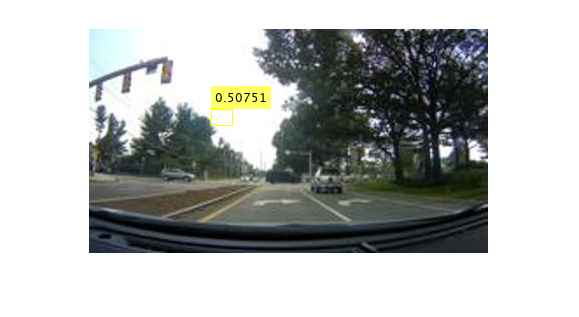

if(~isempty(bboxes))
    I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
end
figure
imshow(I)